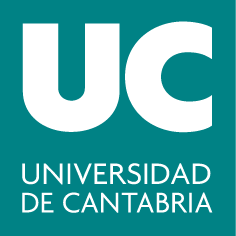

#### ***Grado en Ingeniería ****de los Recursos Energéticos / ****Grado en Ingeniería ****de los Recursos Mineros*

## **Álgebra Lineal y Geometría**

# **Práctica 4:  Aplicaciones Lineales y Diagonalización**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Objetivos	

- Calcular el núcleo y la imagen de una aplicación.

- Calcular los valores propios de un endomorfismo y una base de los subespacios propios.

- Entender la interpretación geométrica de isometrías y su composición.

### Comandos útiles

#### Comandos para el cálculo del núcleo e imagen de una aplicación

- `null(A)`: Devuelve la solución al sistema de ecuaciones homogéneo de matriz de coeficientes `A (`$A\vec{x}=\vec{0}$`)`. Equivale a obtener una **base **(ortonormal cuando no se acompaña del argumento `'r') `**del núcleo de una aplicacion **cuya matriz estándar es A, dado que el núcleo lo forman los vectores ($\vec{x}$) cuya imagen es el vector $\vec{0}$. Ver la práctica 1 para la interpretación del resultado de `null`.

A = [2 0 -5; 0 1 0; 0 0 -6]; % matriz de una aplicación
Ker_f=null(A) % en este ejemplo el núcleo es 0 -> endomorfismo biyectivo


Ker_f =

  3×0 empty double matrix



- `subs(expresion, valor)`: sustituye en una expresion simbolica la(s) incógnita(s) por su valor. Ejemplos:

syms x
subs(3*x, x, 2) % una ecuación con 1 incógnita

$$ans = 6$$

syms x y
subs(3*x+y, [x y], [2 1]) % una ecuación con 2 incógnitas

$$ans = 7$$

syms x y z
subs([x+y+z, x+y-z, z], [x y z], [0 1 0]) % 3 ecuaciones con 3 incógnitas

$$ans = \left(\begin{array}{ccc} 1 & 1 & 0 \end{array}\right)$$

- `rref(A)`: Se obtiene una base del subespacio imagen de una aplicación tomando los vectores (columnas) linealmente independientes de la matriz de la aplicación. Ejemplo:

[RF, pivotes]=rref(A)

RF =      1     0     0
     0     1     0
     0     0     1


pivotes =      1     2     3


Im_f=A(:, pivotes)

Im_f =      2     0    -5
     0     1     0
     0     0    -6


Para calcular la **imagen de un vector **basta con multiplicar la matriz de la aplicacion por el vector. Para calcular la **imagen de un subespacio** basta con  multiplicar la matriz de la aplicación por los vectores que forman un sistema generador del  subespacio e identificar las imágenes linealmente independientes.

#### Comandos para el cálculo de valores y vectores propios

- `eig(A)`: Calcula los valores propios de un endomorfismo.

lambda = eig(A)

lambda =      2
     1
    -6


- `charpoly(A, x)`: Devuelve el polinomio característico asociado a la matriz `A` en términos de la variable `x` definida en simbólico. Ejemplo:

syms vp
p = charpoly(A, vp)

$$p = {\mathrm{vp}}^{3}+3\,{\mathrm{vp}}^{2}-16\,\mathrm{vp}+12$$

- `solve(equation)`: Resuelve ecuaciones algebraicas y sistemas de ecuaciones. Para ello hay que trabajar con las incógnitas en lenguaje simbólico definiéndolas antes de usarlas con la función `syms`, que pertene al paquete `symbolic`. Ejemplo:

lambda = solve(p, vp)

$$lambda = \left(\begin{array}{c} -6\\ 1\\ 2 \end{array}\right)$$

- `diag(x): `Crea una matriz diagonal con los valores del vector x en la diagonal. Ejemplo:

D = diag(lambda)

$$D = \left(\begin{array}{ccc} -6 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 2 \end{array}\right)$$

- `[P, D] = eig(A)`: Calcula los vectores propios (columnas de P; concretamente da una base ortonormal de los subespacios propios) de una matriz **diagonalizable** y la  matriz diagonal del endomorfismo (D). No usar en el caso de matrices no diagonalizables puesto que por problemas de inestabilidad numérica devuelve en las columnas de P vectores iguales como si fueran linealmente independientes.

[P, D] = eig(A)

P =     1.0000         0    0.5300
         0    1.0000         0
         0         0    0.8480


D =      2     0     0
     0     1     0
     0     0    -6


En este ejemplo, la primera columna de `P` es el vector propio asociado a $\lambda=2$ (es decir, base del subespacio propio asociado a $\lambda=2$), la segunda columna de `P` es el vector propio asociado a $\lambda=1$ (es decir, base del subespacio propio asociado a $\lambda=1$) y la tercera columna de `P` es el vector propio asociado a $\lambda=-6$ (es decir, base del subespacio propio asociado a $\lambda=-6$). Por lo tanto, `P` es la matriz de cambio de base de una base a la canónica y en dicha base (dada por las columnas de `P`) la matriz `A` es diagonal. Se comprueba que $A=PDP^{-1}$:

A-P*D*inv(P)

ans = 1.0e-15 *

         0         0         0
         0         0         0
         0         0   -0.8882


#### Comandos para representar vectores

- `quiver(x, y, u, v)`: para representar un vector de coordenadas `(u, v)` con punto de aplicación en `(x, y)`. Por defecto los vectores aparecen escalados, se puede cambiar esa  opción dando el valor 'off' al argumento 'AutoScale' o añadiendo 0 como el quinto argumento de `quiver`. Se puede modificar el tamaño de la cabeza de la flecha con el argumento 'maxheadsize'.

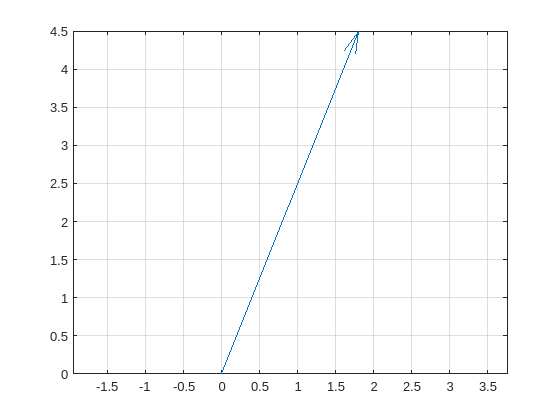

quiver(0, 0, 2, 5), grid on, axis equal

- `title('string')`: Para escribir un título en la parte superior de la figura con el texto en 'string'.

- `legend('string1','string2','string3',…)`: Para incluir una leyenda en la figura, identificando en cada cadena de caracteres lo que se muestra en la figura, en el orden en que se incluyen en la gráfica.

- `grid on / grid off`: Para poner o quitar la cuadrícula del fondo de una figura.

- `axis equal`: Para igualar la escala de todos los ejes coordenados para que la proporción sea 1:1.

- `hold on`: Permite seguir dibujando en la misma figura hasta que aparezca `hold off`.

#### Cambiar el formato de las salidas mostradas

- `format`: Cambia el formato de los resultados.

format rat % Para tener el resultado en formato de cociente (ratio)
format long % Para recuperar el formato decimal con 15 decimales
format short % Para recuperar el formato decimal con 4 decimales

- `double(x)`: Convierte en un valor con doble precisión, no simbólico. Se usa, por ejemplo, sobre el resultado de funciones del paquete `symbolic` como `subs`, `solve`.

### Ejercicios resueltos

*Nota: las lineas de código que terminan en *`;`* no muestran resultado por pantalla, mientras que la mayoría sí lo muestran, para facilitar vuestra comprobación.*

#### **Ejercicio 1: Matriz de una aplicación**

Sea $f: \mathbb{R}^4 \rightarrow \mathbb{R}^4$ una aplicación lineal que verifica que los vectores $(1,1,1,1), (1,1,1,0)$ se transforman por $f$ en $(1,1,0,0), (1,0,0,0)$, respectivamente, y que los vectores $(1, 1, 0, 0), (1, 0, 0, 0)$ forma una base del núcleo de $f$. Halla su matriz estándar.

No conocemos las ecuaciones de la aplicación pero tenemos datos sobre ciertos vectores y sus imágenes. Sabemos que los vectores del núcleo son aquellos cuya imagen es $\vec{0}$. Por lo tanto, conocemos 4 vectores y sus imágenes:

vecAnte = [1 1 1 1; 1 1 1 0; 1 1 0 0; 1 0 0 0]' % vectores antecedentes

vecAnte =      1     1     1     1
     1     1     1     0
     1     1     0     0
     1     0     0     0


vecTrans = [1 1 0 0; 1 0 0 0; 0 0 0 0; 0 0 0 0]' % vectores transformados

vecTrans =      1     1     0     0
     1     0     0     0
     0     0     0     0
     0     0     0     0


Puesto que `vecAntep` y `vecTrans` son matrices cuadradas de orden 4, podemos despejar la matriz de la aplicación A (que también será cuadrada) de la ecuación: `A*vecAnte = vecTrans`

A = vecTrans*inv(vecAnte)

A =      0     0     1     0
     0     0     0     1
     0     0     0     0
     0     0     0     0


#### **Ejercicio 2: Núcleo e imagen**

En $\mathbb{R}^3$ se define la aplicación lineal $f$ de ecuaciones $x' =x + y + z, y' = x + y -z, z'=z$, donde $(x,y,z)$ son las coordenadas de un vector y $(x',y',z')$ las de su asociado después de la transformación, en la base canónica. Se pide: 

a) Núcleo de la aplicación. 

b) Subespacio imagen de la aplicación. 

c) Subespacio imagen asociado a $V$, siendo $V$ el subespacio de $\mathbb{R}^3$ cuya ecuación implícita es $x + y + z = 0$.

d) Hallar la matriz de la apliación $f$ en la base $B=\lbrace(1,1,0), (0, 1, 1), (0, 0, 1)\rbrace$ de $\mathbb{R}^3$.

El enunciado proporciona la ecuación de la aplicación lineal, que se puede escribir también de esta manera:


$$f: \mathbb{R}^3 \rightarrow \mathbb{R}^3\\
(x,y,z)\rightarrow (x+y+z, x+y-z, z)$$


En primer lugar, hallamos la matriz de la aplicación en bases canónicas *𝑓*: `A*[x,y,z]'=[x',y',z']'`.Con MATLAB `p`odemos hallar `A` calculando la imagen de los vectores de la base canónica en $\mathbb{R}^3$ definiendo `x y z` como variables simbólicas y usando `subs`:

syms x y z
u1= double(subs([x+y+z, x+y-z, z], [x y z], [1 0 0]))

u1 =      1     1     0


u2= double(subs([x+y+z, x+y-z, z], [x y z], [0 1 0]))

u2 =      1     1     0


u3= double(subs([x+y+z, x+y-z, z], [x y z], [0 0 1]))

u3 =      1    -1     1


A=[u1' u2' u3']

A =      1     1     1
     1     1    -1
     0     0     1


a) Núcleo de la aplicación. 

Ker_f = null(A) 

Ker_f =    -0.7071
    0.7071
   -0.0000


En columnas, se obtiene una base ortonormal del núcleo de la aplicación f. Por lo tanto, dim(Ker f) = 1. Se puede comprobar que este vector pertenece al núcleo porque su imagen es $\vec{0}$:

A*Ker_f

ans = 1.0e-15 *

    0.0667
    0.1554
   -0.0443


b) Subespacio imagen de la aplicación. 

Dado que el núcleo tiene dimensión 1, necesariamente el subespacio imagen tendrá dimensión 2 porque ambas deben sumar 3 porque el espacio inicial (en este caso también el final) es $\mathbb{R}^3$. Por lo tanto, una base de la imagen la forman dos columnas linealmente independientes de A:

[RF, pivotes]=rref(A);
Im_f = A(:,pivotes)

Im_f =      1     1
     1    -1
     0     1


c) Subespacio imagen asociado a $V$, siendo $V$ el subespacio de $\mathbb{R}^3$ cuya ecuación implícita es $x + y + z = 0$.

La imagen de un sistema generador es sistema generador de la imagen, por lo tanto hallamos la imagen de un sistema generador de V (o una base) y comprobamos si son vectores linealmente independientes.

V = [1 1 1]; % Coeficientes de las ecuaciones implícitas del subespacio V
BaseV = null(V, 'r') % En columnas, base del subespacio V. Si no se pone 'r', la base es ortonormal.

BaseV =     -1    -1
     1     0
     0     1


Im_V = A*BaseV % Sistema generador del subespacio imagen de V

Im_V =      0     0
     0    -2
     0     1


rank(Im_V) 

ans = 1

Dado que el rango es 1 son linealmente dependientes. Una base de la imagen de $V$ viene dada por la segunda columna $(0,-2,1)$.

d) Hallar la matriz de la aplicación $f$ en la base $B=\lbrace(1,1,0), (0, 1, 1), (0, 0, 1)\rbrace$ de $\mathbb{R}^3$.

Sabemos que la matriz A y la matriz de $f$ en la base B (M) se relacionan de la siguiente manera: $M=P^{-1}AP$, siendo $P$ la matriz de cambio de base de B a la base canónica.

p1=[1,1,0]'; p2=[0, 1, 1]'; p3=[0, 0, 1]';
P=[p1 p2 p3] 

P =      1     0     0
     1     1     0
     0     1     1


M=inv(P)*A*P 

M =      2     2     1
     0    -2    -2
     0     3     3


#### **Ejercicio 3: Valores y vectores propios**

Considera el endomorfismo $f$ de $\mathbb{R}^4$ con matriz asociada `A`. 


$$A = \pmatrix{3.2 & 1 & -1 & 2 \cr
                4.7 & 4.2 & -5.7 & 11.4 \cr
                4.7 & 1 & -2.5 & 2 \cr
                0 & 0 & 0 & -1.5 \cr}$$


a) Obtener sus autovalores y la multiplicidad algebraica de cada uno.

b) Obtener los vectores propios y una base de cada subespacio propio. ¿Es `A` diagonalizable?

c) Determinar un antecedente del vector $\vec{v}=(5.40, -0.80, 9.90, 3.75)$, si existe. Si no existe indicarlo expresamente.

d) Justificar si el endomorfismo es inyectivo.

La matriz de la aplicación será:

A=[3.2 1.0 -1 2; 4.7 4.2 -5.7 11.4; 4.7 1 -2.5 2; 0 0 0 -1.5];

a) Obtener sus autovalores y la multiplicidad de cada uno.

format rat
lambda = eig(A) 

lambda =       16/5     
      -3/2     
      16/5     
      -3/2     


Los valores propios o autovalores son -3/2 y 16/5, ambos con multiplicidad algebraica 2.

También se pueden obtener resolviendo la ecuación caracteristica de dos maneras posibles usando `solve`:

syms vp
% Forma 1
lambda = double(solve(det(A-vp*eye(4))))

lambda =       -3/2     
      -3/2     
      16/5     
      16/5     


% Forma 2
lambda = double(solve(charpoly(A, vp)))

lambda =       -3/2     
      -3/2     
      16/5     
      16/5     


b) Obtener los vectores propios y una base de cada subespacio propio. ¿Es `A` diagonalizable?

Forma 1: resolviendo los SCI homogéneos asociados a cada valor propio.

format short
V1=null(A-lambda(1)*eye(4)) % asociado al primer valor propio (-3/2)

V1 =    -0.0000   -0.0000
   -0.9129   -0.0000
   -0.1826    0.8944
    0.3651    0.4472


V2=null(A-lambda(3)*eye(4))% asociado al segundo valor propio (16/5)

V2 =    -0.5774
   -0.5774
   -0.5774
   -0.0000


Por lo tanto una base del subespacio propio asociado a $\lambda_{1}=-\frac{3}{2}$ viene dada por las columnas de V1 (dim V1=2) y una base del subespacio propio asociado a $\lambda_{2}=\frac{16}{5}$ viene dada por la columna de V2 (dim V2=1).

Comprobamos que las columnas de V1 son vectores propios con valor propio $\lambda_{1}=-\frac{3}{2}$ y que V2 es vector propio con valor propio $\lambda_{2}=\frac{16}{5}$, es decir, comprobamos que $A\vec{v}=\lambda\vec{v} \Rightarrow A\vec{v}-\lambda\vec{v}=\vec{0}$

A*V1(:,1)-lambda(1)*V1(:,1)

ans = 1.0e-15 *

   -0.0550
    0.4441
   -0.1110
         0


A*V1(:,2)-lambda(1)*V1(:,2)

ans = 1.0e-15 *

   -0.0393
   -0.2384
   -0.2220
         0


A*V2-lambda(3)*V2

ans = 1.0e-14 *

         0
    0.0666
    0.1554
    0.0131


Observamos que la multiplicidad algebraica del autovalor $\lambda_{1}=-\frac{3}{2}$ era 2 y la dimensión del  subespacio asociado es 2 y que la multiplicidad algebraica del autovalor $\lambda_{2}=\frac{16}{5}$ era 2, pero la dimensión  del subespacio asociado (número de vectores l.i. del subespacio propio, multiplicidad geométrica) es 1. Dado que la suma de las dos dimensiones es 3 y es un endomorfismo en $\mathbb{R}^4$ concluimos que no es diagonalizable.

También podríamos haber calculado en primer lugar la dimensión de los subespacios propios, para determinar si el endormorfismo es diagonalizable. Para que sea diagonalizable, la suma de las dimensiones de los subespacios propios debe ser 4 y cada dimensión se puede calcular con: $dim(V_{i})=n-rg(A-\lambda_{i} I)$ donde $n$ es la dimensión del espacio vectorial (en este ejemplo 4) y $\lambda_{i}$ cada uno de los valores propios:

n = 4;
dimV1 = n - rank(A-lambda(1)*eye(n))

dimV1 = 2

dimV2 = n - rank(A-lambda(3)*eye(n))

dimV2 = 1

Dado que no suman 4, no es diagonalizable.

Forma 2: Con el comando `eig` y comprobando que la dimensión de cada subespacio coincide con la multiplicidad algebraica del valor propio.

[P D]=eig(A)

P =     0.5774   -0.0000    0.5774   -0.0000
    0.5774   -0.7071    0.5774   -0.8430
    0.5774   -0.7071    0.5774    0.1747
         0         0         0    0.5088


D =     3.2000         0         0         0
         0   -1.5000         0         0
         0         0    3.2000         0
         0         0         0   -1.5000


V1=P(:,[2 4]) % columnas 2 y 4 para -3/2

V1 =    -0.0000   -0.0000
   -0.7071   -0.8430
   -0.7071    0.1747
         0    0.5088


V2=P(:,[1 3]) % columnas 1 y 3 para 16/5

V2 =     0.5774    0.5774
    0.5774    0.5774
    0.5774    0.5774
         0         0


rank(V1) % dim V1=2

ans = 2

rank(V2) % dim V2=1

ans = 1

Por lo tanto una base del subespacio propio asociado a $\lambda_{1}=-\frac{3}{2}$ viene dada por las columnas de V1 y una base del subespacio propio asociado a $\lambda_{2}=\frac{16}{5}$ viene dada por una de las columnas de V2 (son iguales).

Notar que obtenemos bases distintas para los subespacios propios (en este ejemplo para V1) al usar `eig` y al resolver los sistemas porque `eig` devuelve una base ortonormal (vectores ortogonales entre sí y unitarios), pero ambas son correctas.

**Importante:** A pesar de ser no diagonalizable, el comando `eig` devuelve la matriz D. En efecto, P tiene dos columnas iguales por lo tanto no es invertible (su determinante es 0), por lo tanto, no es posible expresar A como $PDP^{-1}$. No es aconsejable usar en este caso `[P D]=eig(A)` para evitar interpretaciones incorrectas de P y D`.`

det(P)

ans = -1.6143e-16

c) Determinar un antecedente del vector $\vec{v}=(5.40, -0.80, 9.90, 3.75)$, si existe. Si no existe indicarlo expresamente.

El vector $\vec{v}$ tendrá antecedente $\vec{x}$ siempre que el sistema $A\vec{x}=\vec{v}$ sea compatible.

v=[5.4 -0.8 9.9 3.75]'; 
[rank(A) rank([A v])]

ans =      4     4


Al ser iguales los rangos el sistema es compatible determinado y resoluble por varios métodos:

x=linsolve(A,v); % Forma 1
x= A\v; % Forma 2
rref([A v]); % Forma 3. La última columna de la forma reducida por filas nos da como antecedente x=(2,3,-1,5/2)
x= inv(A)*v % Forma 4

x =     2.0000
    3.0000
   -1.0000
   -2.5000


d) Justificar si el endomorfismo es inyectivo.

El endomorfismo es inyectivo si la dimensión del núcleo es cero (inyectivo) y la de la imagen es 4 (suprayectivo/sobreyectivo).

[RF, pivotes]=rref(A)

RF =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


pivotes =      1     2     3     4


Por lo tanto el endomorfismo $f$ SÍ es inyectivo pues $dim(Im f)=rg(A)=4 \Rightarrow dim(Ker f)=dim(R4)-dim(Im f)=4-4=0$

#### **Ejercicio 4: Aplicaciones con interpretación geométrica sencilla en **$\mathbb{R}^2$

Sea $f: \mathbb{R}^2 \rightarrow \mathbb{R}^2$ la aplicación que gira un vector $\frac{\pi}{4}$ en sentido antihorario (matriz $F$) y sea $g$ la reflexión respecto de la recta $x=y$ (matriz $G$):


$$F = \pmatrix{\frac{\sqrt{2}}{2} & -\frac{\sqrt{2}}{2} \cr
                \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2} \cr}  $$
                
$$G = \pmatrix{0 & 1\cr
                1 & 0 \cr}$$
            

Se pide hallar y representar en el plano las siguientes imágenes para el vector $\vec{v}=(1,2)$. Comprobar que la norma se conserva en todas las transformaciones.

a) $f(\vec{v})$

b) $g(\vec{v})$

c) $(g \circ f) (\vec{v})$

d) $(f \circ g) (\vec{v})$

En primer lugar, introducimos las matrices de las dos aplicaciones y el vector:

v=[1 2]';
F=[sqrt(2)/2 -sqrt(2)/2; sqrt(2)/2 sqrt(2)/2];
G=[0 1; 1 0];

a) $f(\vec{v})$

f_v = F*v % Rotación 

f_v =    -0.7071
    2.1213


b) $g(\vec{v})$

g_v = G*v % Reflexión

g_v =      2
     1


c) $(g \circ f) (\vec{v})$

gf_v = G*F*v % Primero rotación, luego reflexión

gf_v =     2.1213
   -0.7071


d) $(f \circ g) (\vec{v})$

fg_v = F*G*v % Primero reflexión, luego rotación

fg_v =     0.7071
    2.1213


Representamos gráficamente con la función `quiver`:

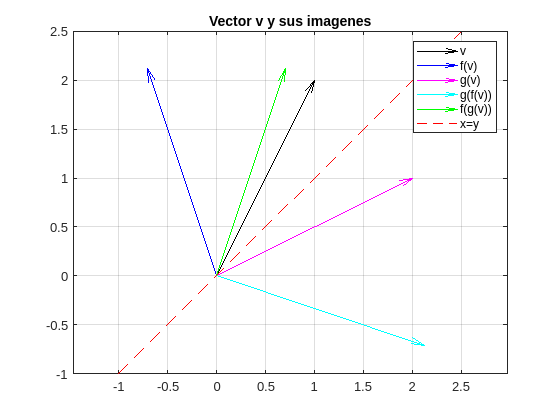

figure(1)
quiver(0,0, v(1), v(2), 'AutoScale','off','Color','k')
hold on
quiver(0,0, f_v(1), f_v(2), 'Color','b','AutoScale','off')
quiver(0,0, g_v(1), g_v(2),'Color','m', 'AutoScale','off')
quiver(0,0, gf_v(1), gf_v(2),'Color','c', 'AutoScale','off')
quiver(0,0, fg_v(1), fg_v(2),'Color','g', 'AutoScale','off')
plot([-1 2.5],[-1 2.5], '--','Color','r')
title('Vector v y sus imagenes')
grid on
axis equal
legend('v','f(v)', 'g(v)', 'g(f(v))', 'f(g(v))', 'x=y')
hold off

Se comprueba que la norma del vector después de todas estas transformaciones se conserva, dado que se trata de isometrías:

[norm(v)-norm(f_v) norm(v)-norm(g_v) norm(v)-norm(gf_v) norm(v)-norm(fg_v)]

ans =      0     0     0     0


### Ejercicios propuestos

Se propone resolver con MATLAB los ejercicios de las hojas de problemas de los temas 5, 6 y 7, en especial: 

- **5.2, 5.6** del tema de aplicaciones lineales.

- **6.6, 6.7** del tema de endomorfismos y diagonalización.

- **7.1 **de aplicaciones geométricas.